# Lab 5: Higgs Classification

*In this problem we are going to look at an inclusive search for the standard model Higgs boson in pp collisions at √ s = 13 TeV at the LHC using simulated data [*[*A. Schuy*](https://github.com/AlexSchuy/qsvm_jet_tagging/tree/master/qsvm_jet_tagging/generation)*]. The Higgs bosons are produced with large transverse momentum (pT) and decaying to a bottom quark-antiquark pair. The Higgs candidates could be reconstructed as large-radius jets using Calorimeters. Due to large QCD backgorund containmination, the direct 5-sigma observation of this Higgs channel is not accomplished yet[*[*Phys. Rev. Lett. 120, 071802 (2018)*](https://arxiv.org/abs/1709.05543)*]. We are going to use a set of training datasets to optimize event selections in order to enhance the discovery sensitivity. The optimal event selections will be applied to a selected pseudo-experiment data.*

clear all; close all; clc;
tic;
h5disp("higgs_100000_pt_250_500.h5")

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


higg1 = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500')

higg1 =   472.0743  470.4057  438.0084  484.8604  486.1411  475.7986  470.8149  471.7346  483.0434  484.3594  483.7841  355.7144  447.8510  470.9453  463.7351  464.7159  422.0606  484.4623  439.5814  398.7205  399.5736  462.6961  472.1019  479.4185  483.3924  365.2780  340.5481  464.9933  478.3722  400.5985  406.1833  395.6889  473.0330  461.3767  387.7750  484.1580  481.7607  468.3420  484.5389  469.9644  457.3494  369.5277  472.3923  482.9357  468.1657  441.4369  461.7004  484.8110  480.1680  472.0944
    0.1371   -0.0392   -0.1811    0.2520   -1.9178    1.6790   -2.1232    1.5648    1.0580    1.0767   -0.5663    0.0301    0.8057    0.1346   -0.7741   -0.6319    0.1981    1.3883    0.5352    0.1998    1.1904    0.6664   -1.3298   -0.0255   -0.9671    1.0838    1.3166    1.0197   -0.9716    0.2463   -1.7009   -0.7605    0.9052   -0.3085    1.2665   -0.6532    0.9413   -0.7770   -0.2713    0.2914   -0.4328   -0.1204    0.5083   -0.3029    0.6362   -0.4280   -1.8455   -0.2713    1.0133 

h5disp("higgs_100000_pt_250_500.h5")

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


qcd1 = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500')

qcd1 =   489.6314  401.0419  447.4876  402.6528  484.2577  499.0071  457.7036  374.4903  419.8250  474.3015  467.3567  459.7810  471.2043  440.2651  385.7577  435.3643  337.2852  405.7670  458.1654  427.7713  415.0766  421.6481  470.9418  482.5692  442.5056  446.6566  452.9548  476.5917  453.7044  389.6286  389.0915  428.4388  458.8233  483.5187  478.9330  441.0455  424.8774  427.1197  414.5757  450.4949  418.8596  420.4721  487.0326  471.5173  448.6381  477.7887  441.2891  435.1772  456.8878  437.5076
    1.9560   -1.1704    1.8617    1.2764   -1.2722   -0.8524   -0.3995   -1.7677   -2.4050    0.3572    0.1360   -0.2347   -0.5590   -0.1839   -0.5735   -1.3363    0.9365    1.6993   -0.6131   -1.2244   -1.5068    2.0155    1.2859   -0.4823   -1.9143   -1.2203   -2.1137   -1.8622    0.5655    2.3071   -2.0039    1.8233   -0.9524   -1.2294   -0.5424   -1.7241   -1.5639    0.0833   -0.6424   -1.2551    0.8249    2.1431   -0.2594   -2.0814   -1.2874   -1.7915    0.1968   -0.0421    1.3049  

Comparing Higgs data (in blue) with QCD data (in yellow)

Here we are comparing the **transverse momentum** values of the Higgs and the QCD data. Transverse momentum is the momentum of the interacting particles involved in the event while non-transverse momentum is the one associated with the non-interacting particles involved in the event.

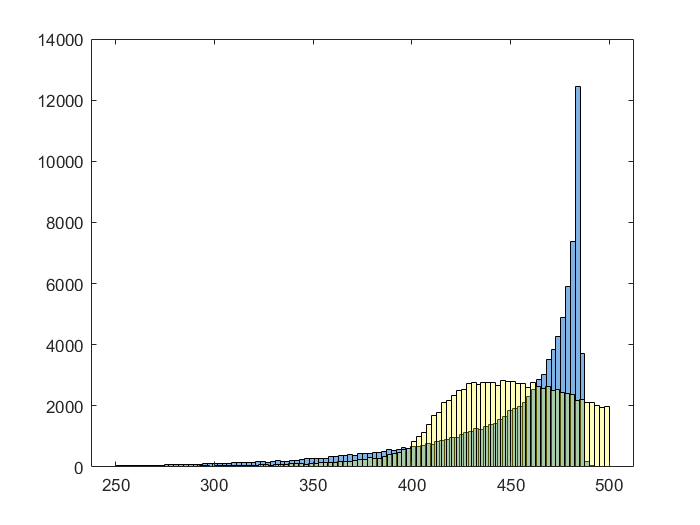

hTransverseMomentum = higg1(1,:);
histogram(hTransverseMomentum,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
qTransverseMomentum = qcd1(1,:);
histogram(qTransverseMomentum,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

Looking at the graph, while the transverse momentum of an average qcd event is in the same range as the events associated with Higgs in the Higgs distribution we see a large spike for larger values of transverse momentum. We also see a significant portion of QCD events with high values of transverse momentum as well so we can't be certain that an event with a high transverse momentum is an appearance of the Higgs.

Comparing **pseudorapidity, **the measurement of the angle between the particle and the beam axis; events with low pseudorapidity are registered, while the events with higher pesudorapidity are generally lost.

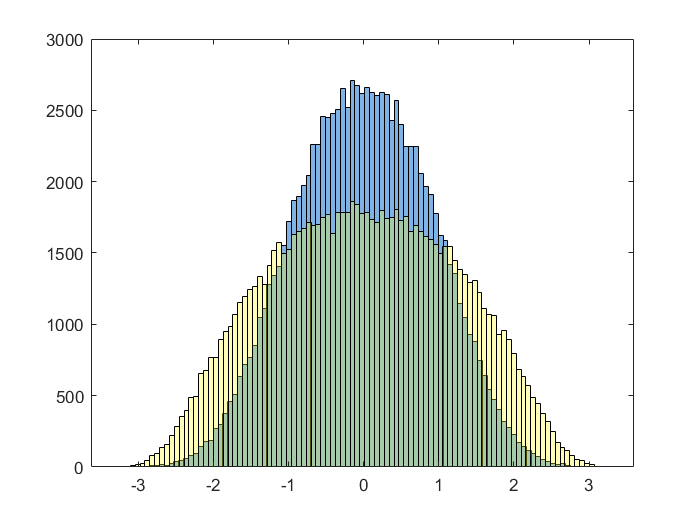

hPseudorapidity = higg1(2,:);
histogram(hPseudorapidity,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
qPseudorapidity = qcd1(2,:);
histogram(qPseudorapidity,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

The Higgs and QCD data looks very similar here. They have a virtually identical mean of zero and are both normal distributions with probably very similar sigma values so it is difficult to differentiate between the Higgs and QCD here.

Here we are comparing the **azimuthal angle, **the measure of the angle from the x-axis around the beam.

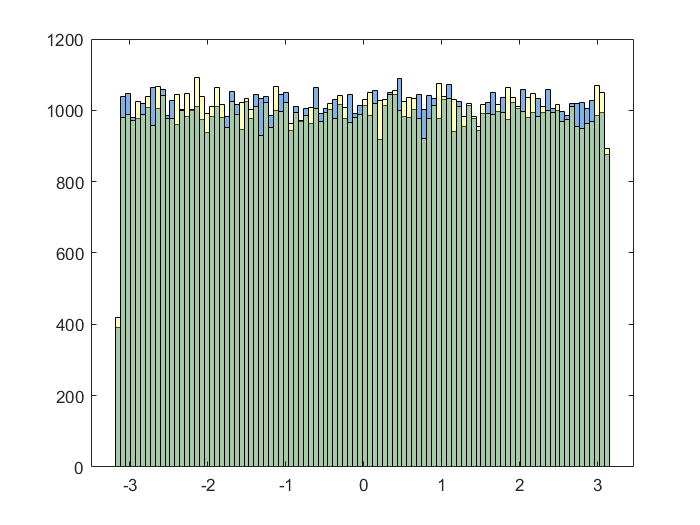

hAzimuthAngle = higg1(3,:);
histogram(hAzimuthAngle,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
qAzimuthAngle = qcd1(3,:);
histogram(qAzimuthAngle,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

This is probably the most interesting one yet as there appears to be no discernable patterns for either the Higgs nor the QCD data except for the fact that they are very nearly identical and it seems that all events are equally likely, therefore this isn't a good method to identify Higgs particle's.

Comparing** invariant masses, **the portion of the total mass of the system that is independent of the overall motion of the system:

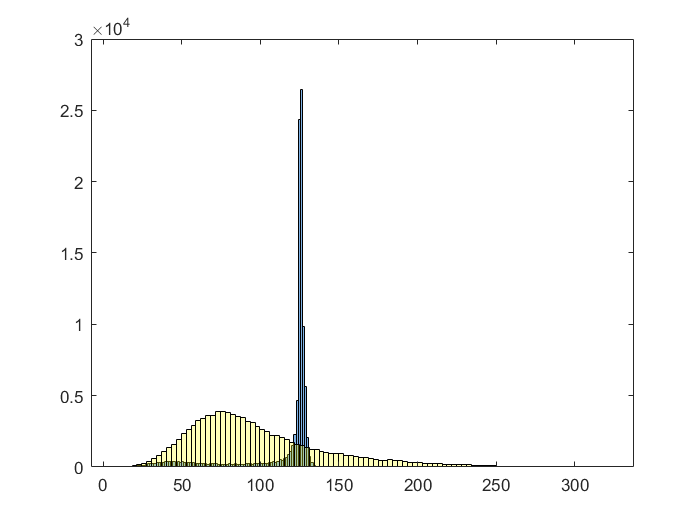

hInvariantMass = higg1(4,:);
histogram(hInvariantMass,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
qInvariantMass = qcd1(4,:);
histogram(qInvariantMass,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

hInvarAvg = mean(hInvariantMass)

hInvarAvg = 114.8924

hInvarSTD = std(hInvariantMass)

hInvarSTD = 25.3511

qInvarAvg = mean(qInvariantMass)

qInvarAvg = 97.7380

qInvarSTD = std(qInvariantMass)

qInvarSTD = 43.4929

STD is large and skewed due to some higgs picked up on the left side of the graph, and this distribution is not a normal distribution so the STD is not very useful. 

Using the range of 120-132 which is where the spike appears to be, we created a list of the indices of the QCD data points where that mass range is within that spike.

newIndex(1) = 0;
newLength = 1;
for i=1:length(qInvariantMass)
    if (qInvariantMass(i) > 120 && qInvariantMass(i) < 132)
        newIndex(newLength) = i;
        newLength = newLength +1;
    end
end

Plotting the qcd data of the new indices:

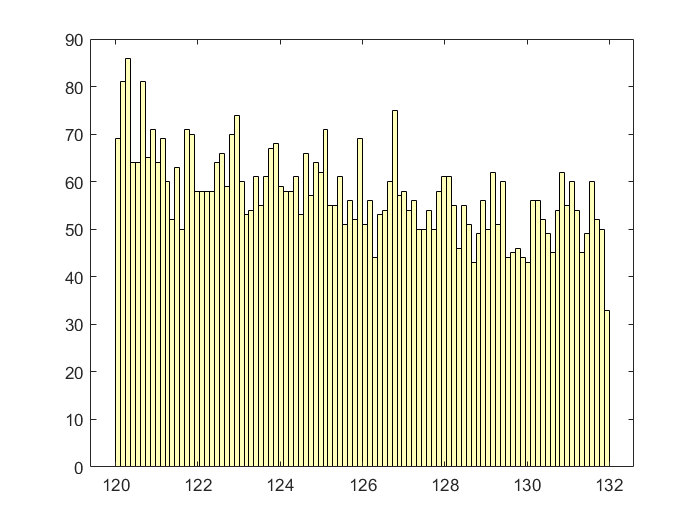

newQInvariantMass = qInvariantMass(newIndex);
histogram(newQInvariantMass,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)

Comparing the **2 point ECF ratio (2PECFR)**, which is the energy correlation ratio:

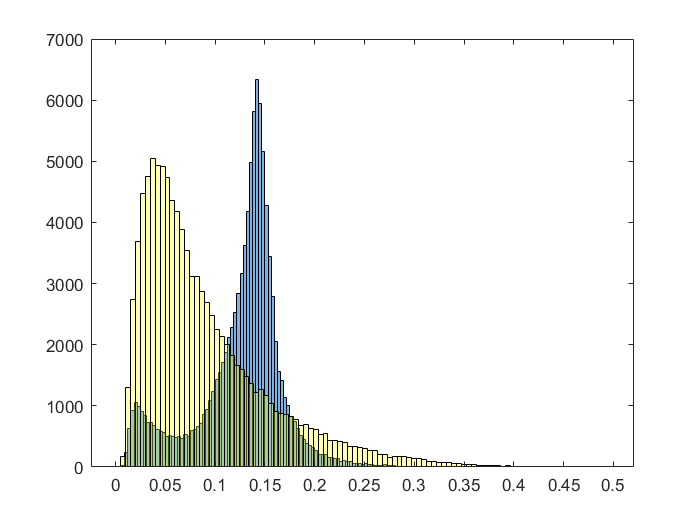

h2PointECFratio = higg1(5,:);
histogram(h2PointECFratio,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
q2PointECFratio = qcd1(5,:);
histogram(q2PointECFratio,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

The 2PECFR attributed to the Higgs data has a larger mean than the 2PECFR of the QCD data, but we still see a a significant amount of overlap between the two sets of data. They also have differing distributions: QCD 2PECFR follows a Poisson distribution with a median at about 0.05 while the Higgs data has two spikes at approximately 0.25 & 0.14.

Comparing the **3 point ECF ratio (3PECFR)**, which is the energy correlation ratio:

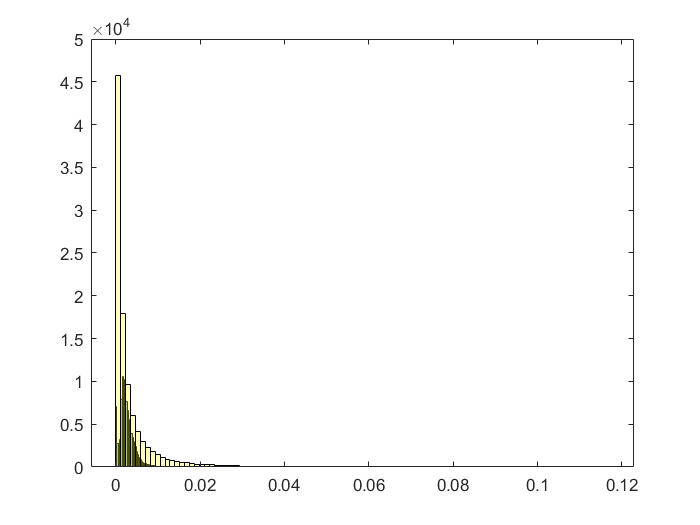

h3PointECFratio = higg1(6,:);
histogram(h3PointECFratio,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
q3PointECFratio = qcd1(6,:);
histogram(q3PointECFratio,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

They both appear to have similar distributions and the Higgs data is entirely within the range of the QCD data. We also see a massive spike in the QCD data very close to zero.

Comparing the **3 to 2 point ECF ratio (3-2PECFR). **

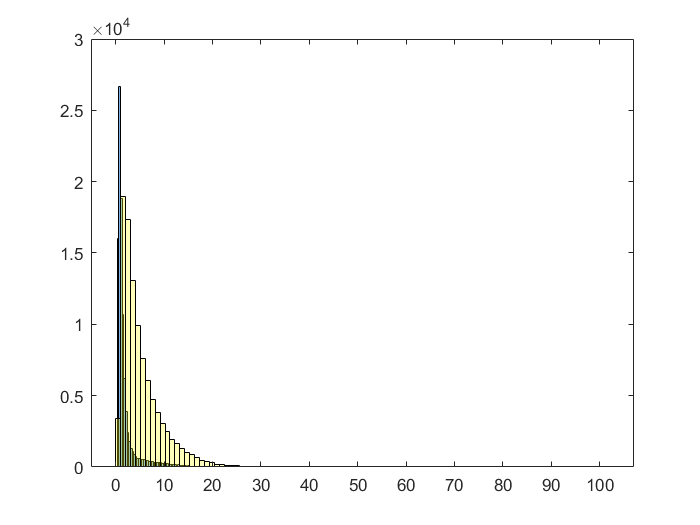

h3to2pointECFratio = higg1(7,:);
histogram(h3to2pointECFratio,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
q3to2pointECFratio = qcd1(7,:);
histogram(q3to2pointECFratio,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

Once again we see a very similar distribution with the QCD data having a larger range, however this time we see a spike in the Higgs data near zero.

Comparing **angularity:**

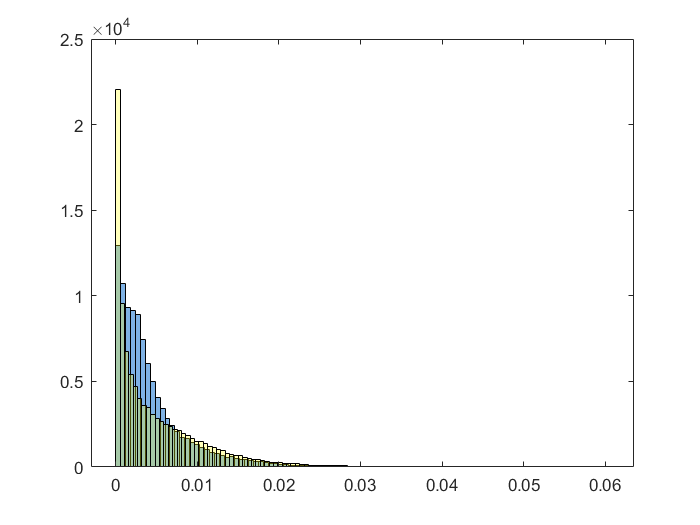

hAngularity = higg1(8,:);
histogram(hAngularity,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
hold on;
qAngularity = qcd1(8,:);
histogram(qAngularity,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off;

They're pretty much identical except the Higgs is slightly more common at lower values.

Comparing **variable 9:**

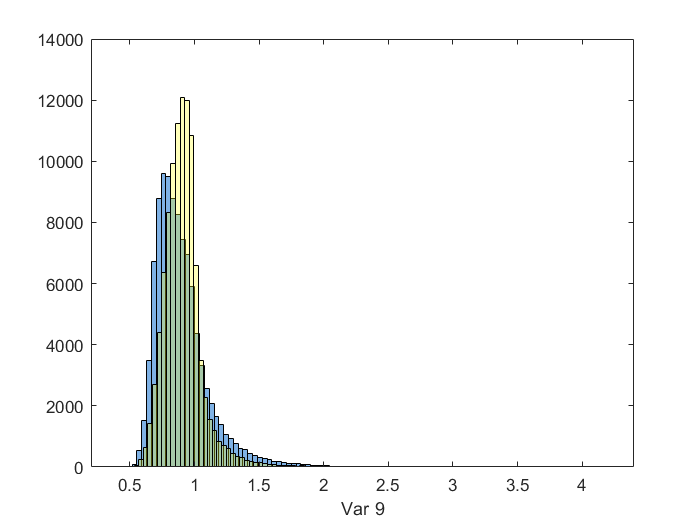

hvar9 = higg1(9,:);
histogram(hvar9,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
xlabel 'Var 9'
hold on
qvar9 = qcd1(9,:);
histogram(qvar9,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off

While the median values are slightly different, the two sets of data seem to have similar characteristics. 

Comparing **variable 10**

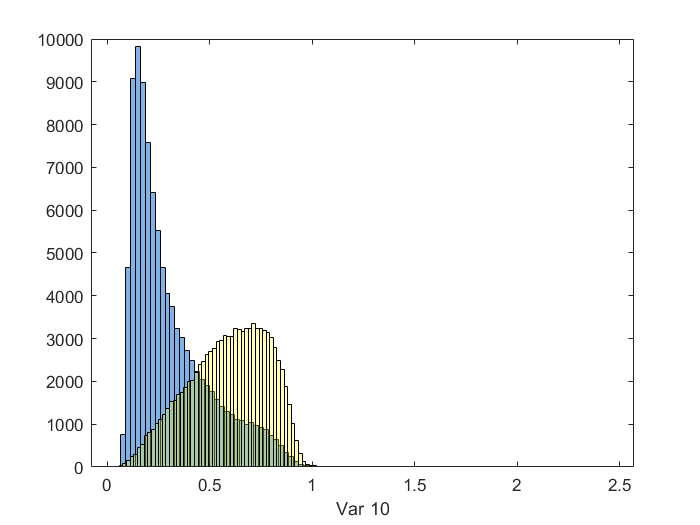

hvar10 = higg1(10,:);
histogram(hvar10,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
xlabel 'Var 10'
hold on
qvar10 = qcd1(10,:);
histogram(qvar10,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off

Higgs variable 10 is Poisson distributed with a significantly smaller median than the QCD data, which is distributed towards larger values..

Comparing **variable 11**

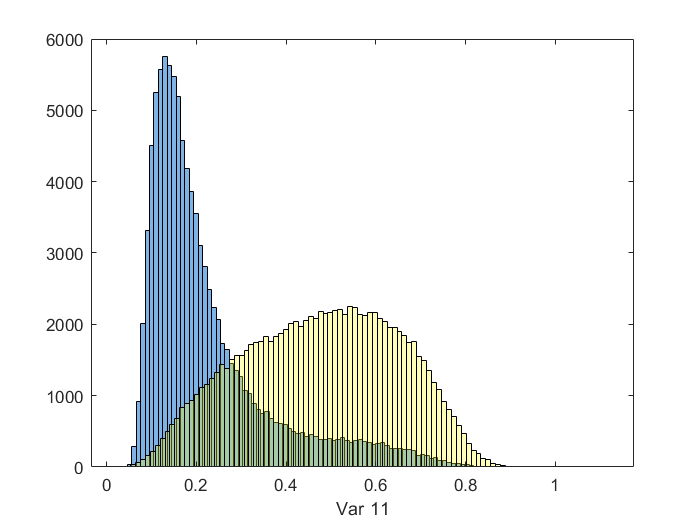

hvar11 = higg1(11,:);
histogram(hvar11,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
xlabel 'Var 11'
hold on
qvar11 = qcd1(11,:);
histogram(qvar11,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off

Comparing **variable 12**

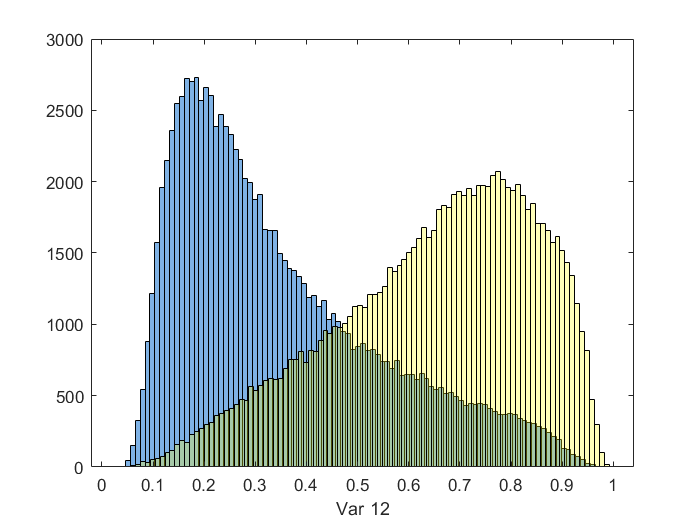

hvar12 = higg1(12,:);
histogram(hvar12,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
xlabel 'Var 12'
hold on
qvar12 = qcd1(12,:);
histogram(qvar12,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off

Comparing **variable 13**

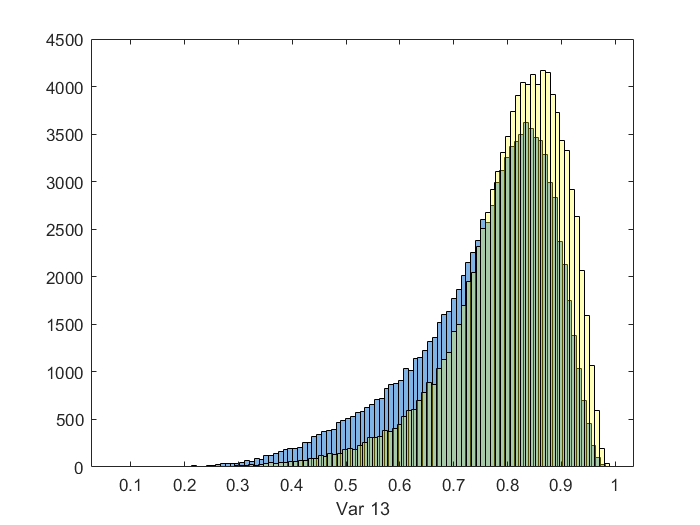

hvar13 = higg1(13,:);
histogram(hvar13,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
xlabel 'Var 13'
hold on
qvar13 = qcd1(13,:);
histogram(qvar13,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off

Variables 11,12, and 13 share similarities, where all of them cover the range of 0-1. Higgs data's median is approximately 0.2 for 11 and 12 while the median for the QCD data is 0.55 for 11, and 0.75 for 12. These variables could potentially be used to identify Higgs. Variable 13 however, both QCD and Higgs look nearly identical and could not be used to identify either Higgs nor QCD.

Comparing **variable 14**

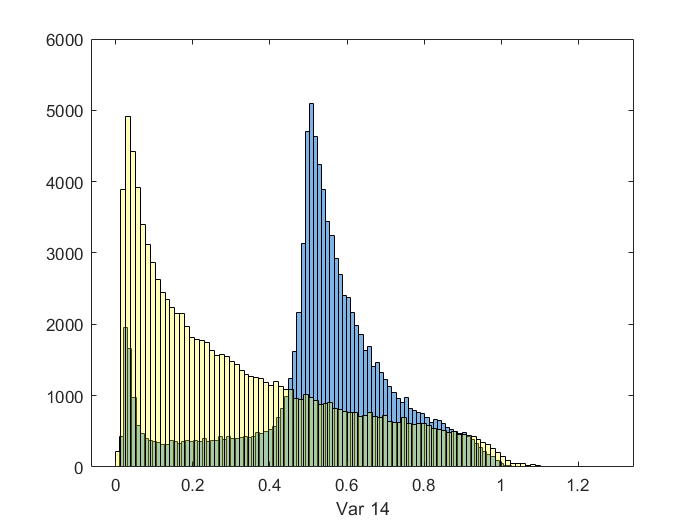

hvar14 = higg1(14,:);
histogram(hvar14,100,'FaceColor',[0,.4,.8],'FaceAlpha',0.5)
xlabel 'Var 14'
hold on
qvar14 = qcd1(14,:);
histogram(qvar14,100,'FaceColor',[1,1,.1],'FaceAlpha',0.3)
hold off

The Higgs distribution spikes at 0.5 while the QCD distribution has a spike around 0.05. Both of these distributions are spread across a similar range of values so while this variable could potentially identify the Higgs, it shouldn't be used alone to say for certain whether you have found a Higgs particle or not.

In conclusion, the data provided, when used in combination with eachother, can be used to determine whether a Higgs particle has been detected with a reasonable amount of certainty.

toc

Elapsed time is 10.536091 seconds.
